# Proyecto 2 Metodos

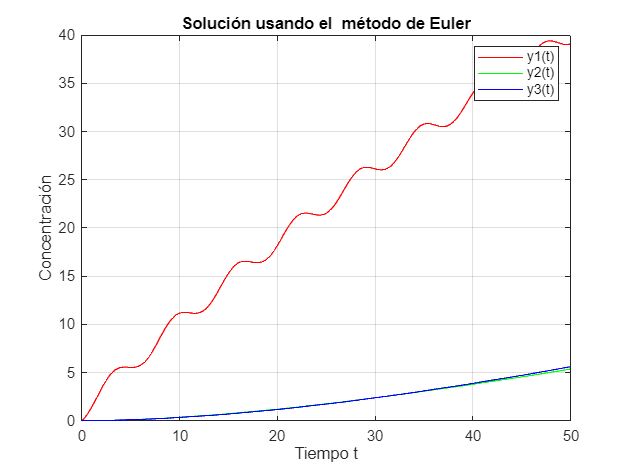

% Inicialización de Variables y Condiciones Iniciales segun el paper
F13 = 38;
F31 = 18;
F21 = 20;
F32 = 18;
V1 = 2900;
V2 = 850;
V3 = 1180;
% Condiciones iniciales
mu1 = 0; 
mu2 = 0; 
mu3 = 0; 
mu = [mu1; mu2; mu3];  % Vector de condiciones iniciales para el método de Boubaker

% Definición de la función de entrada de contaminantes
p = @(t) 1 + sin(t);

% Definir el intervalo de tiempo para la simulación
a=0;
b=50;
h=0.1;

% Definir parametros para Boubaker
M = 3; % Cantidad de funciones (Param)
N = 10; % Cantidad de punts de Boubaker (Param)

y1_prime = @(t, y1, y2, y3) (F13/V3) * y3 + p(t) - (F31/V1) * y1 - (F21/V1) * y1;
y2_prime = @(t, y1, y2, y3) (F21/V1) * y1 - (F32/V2) * y2;
y3_prime = @(t, y1, y2, y3) (F31/V1) * y1 + (F32/V2) * y2 - (F13/V3) * y3;

f = @(t, y) [
    y1_prime(t, y(1), y(2), y(3));
    y2_prime(t, y(1), y(2), y(3));
    y3_prime(t, y(1), y(2), y(3));
];

[t, y] = euler(f, a, b, mu, h);

figure;
plot(t, y(1, :), 'r', t, y(2, :), 'g', t, y(3, :), 'b');
legend('y1(t)', 'y2(t)', 'y3(t)');
xlabel('Tiempo t');
ylabel('Concentración');
title('Solución usando el  método de Euler');
grid on;

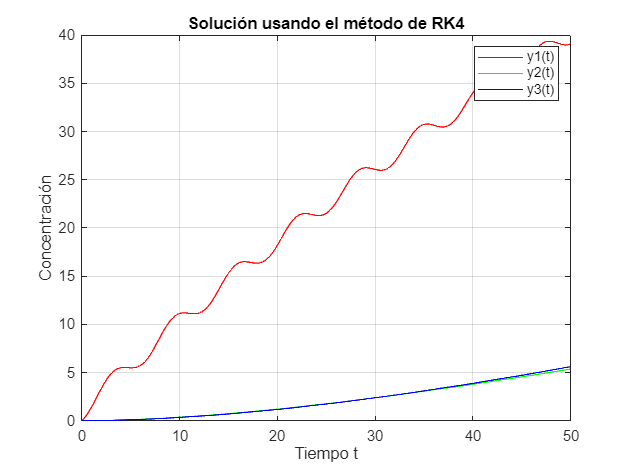


[t,y] = rk4(f, a, b, mu, h);
figure;
plot(t, y(1, :), 'r', t, y(2, :), 'g', t, y(3, :), 'b');
legend('y1(t)', 'y2(t)', 'y3(t)');
xlabel('Tiempo t');
ylabel('Concentración');
title('Solución usando el método de RK4');
grid on;

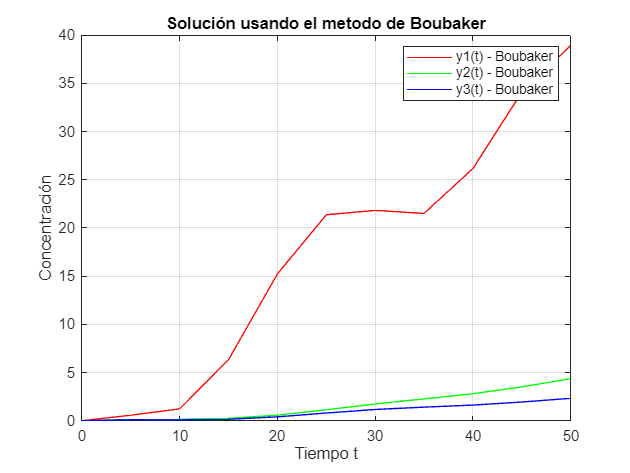


[t_values, y_boubaker] = Boubakerf(M, N, b, p, mu, [F13; F31; F21; F32], [V1, V2, V3]);

y_boubaker_eval = zeros(3, length(t_values));
for i = 1:length(t_values)
    y_boubaker_eval(1, i) = y_boubaker{1}(t_values(i));
    y_boubaker_eval(2, i) = y_boubaker{2}(t_values(i));
    y_boubaker_eval(3, i) = y_boubaker{3}(t_values(i));
end

figure;
plot(t_values, y_boubaker_eval(1, :), 'r', t_values, y_boubaker_eval(2, :), 'g', t_values, y_boubaker_eval(3, :), 'b');
legend('y1(t) - Boubaker', 'y2(t) - Boubaker', 'y3(t) - Boubaker');
xlabel('Tiempo t');
ylabel('Concentración');
title('Solución usando el metodo de Boubaker');
grid on;

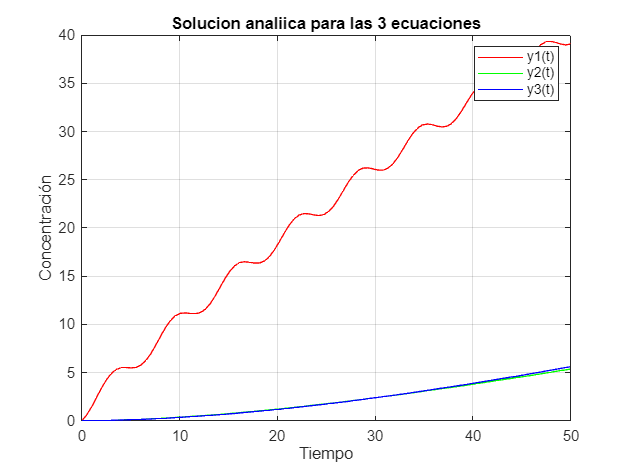

% Solución analítica usando dsolve
syms y1(t_var) y2(t_var) y3(t_var) t_var
p_sym = 1 + sin(t_var); 

eq1 = diff(y1, t_var) == (F13/V3) * y3 + p_sym - (F31/V1 + F21/V1) * y1;
eq2 = diff(y2, t_var) == (F21/V1) * y1 - (F32/V2) * y2;
eq3 = diff(y3, t_var) == (F31/V1) * y1 + (F32/V2) * y2 - (F13/V3) * y3;

condiciones = [y1(0) == 0, y2(0) == 0, y3(0) == 0];
sol = dsolve([eq1, eq2, eq3], condiciones);
y1_func = matlabFunction(simplify(sol.y1));
y2_func = matlabFunction(simplify(sol.y2));
y3_func = matlabFunction(simplify(sol.y3));

t_vals = linspace(0, 50, 100);
y1_vals = y1_func(t_vals);
y2_vals = y2_func(t_vals);
y3_vals = y3_func(t_vals);

figure;
plot(t_vals, y1_vals, 'r', t_vals, y2_vals, 'g', t_vals, y3_vals, 'b');
legend('y1(t)', 'y2(t)', 'y3(t)');
xlabel('Tiempo');
ylabel('Concentración');
title('Solucion analiica para las 3 ecuaciones');
grid on;


%Se iterpolan los 3 metodos con el fin de poder sacarles su MSE y ver que tan buenos son
y_euler_interp = interp1(t, y', t_vals, 'linear', 'extrap')';
y_rk4_interp = interp1(t, y', t_vals, 'linear', 'extrap')';
y_boubaker_interp = interp1(t_values, y_boubaker_eval', t_vals, 'linear', 'extrap')';

%Se calcula el MSE (Mean Square Error) De cada metodo
mse_euler = mean((y_euler_interp - [y1_vals; y2_vals; y3_vals]).^2, 2);

mse_euler = 1.0e-06 *

    0.4125
    0.0000
    0.0000


mse_rk4 = mean((y_rk4_interp - [y1_vals; y2_vals; y3_vals]).^2, 2);

mse_rk4 = 1.0e-06 *

    0.4125
    0.0000
    0.0000


mse_boubaker = mean((y_boubaker_interp - [y1_vals; y2_vals; y3_vals]).^2, 2);

mse_boubaker =    32.5051
    0.4591
    2.4264



mse_euler_general =mean(mse_euler)

mse_euler_general = 1.3753e-07

mse_rk4_general =mean(mse_rk4)

mse_rk4_general = 1.3753e-07

mse_boubaker_general =mean(mse_boubaker)

mse_boubaker_general = 11.7969

function [t, y] = euler(f, a, b, y0, h)
    t = a:h:b;                
    y = zeros(length(y0), length(t));
    y(:,1) = y0;

    for i = 1:(length(t) - 1)
        y(:,i+1) = y(:,i) + h * f(t(i), y(:,i));
    end
end

function [t, y] = rk4(f, a, b, y0, h)
    t = a:h:b;                
    y = zeros(length(y0), length(t));  
    y(:,1) = y0;

    for i = 1:(length(t) - 1)
        k1 = h * f(t(i), y(:,i));
        k2 = h * f(t(i) + h/2, y(:,i) + k1/2);
        k3 = h * f(t(i) + h/2, y(:,i) + k2/2);
        k4 = h * f(t(i) + h, y(:,i) + k3);
        
        y(:,i+1) = y(:,i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
    end
end

function [t_val, y] = Boubakerf(M,N,b,p,mu,F_values,V_values)
syms t
i = 0:1:N; %Calculo de puntos
t_val=(b/N)*i; %Valores de t a partir de los puntos

A = sym('a', [N+1, M]); % Generar matriz de coeficientes de Boubaker a encontrar

Y = sym('Y', [1, N+1]); % Generacion de valores de Y

for k = 1:N+1
    Y(k) = t^(k-1); %Llenado del vector con las potencias
end


Y_val = zeros(length(t_val), N+1); %Conjunto de todos los valores posibles a partir de los grados maximos y de los puntos dados
for j = 1:length(t_val)
    Y_val(j, :) = subs(Y, t, t_val(j));
end


M = eye(N+1); %Se genera la matriz M

phi = @(m, n) ((m - 4*n) / (m - n)) * nchoosek(m - n, n) * (-1)^n; %Funcion de llenado de los elementos de la matriz

for row = 2:N+1
    for col = 1:row-1
        if mod(row + col, 2) == 0
            if mod(N, 2) == 0 %Rellenado si es que es par
                m = row - 1; 
                n = floor((row - col) / 2);
                if m > n && n >= 0
                    M(row, col) = phi(m, n);
                end
            else %Rellenado si es impar
                m = row - 1;
                n = floor((row - col) / 2);
                if m > n && n >= 0 
                    M(row, col) = phi(m, n);
                end
            end
        end
    end
end

M=M'; %Se traspone los valores de la matriz;

D_diag = diag(1:N);
D = zeros(N+1);

D(1:N, 2:N+1) = D_diag; %Se define la matriz D, con los valores de los puntos

%%Definicion de las condiciones iniciales según boubaker
cond1 = Y_val(1, :)*M* A(:, 1)==mu(1);
cond2 = Y_val(1, :)*M* A(:, 2)==mu(2);
cond3 = Y_val(1, :)*M* A(:, 3)==mu(3);

eqs = []; %Espacio para guardar las ecuaciones

%Se definen cada ecuacion, reemplazando los valores de Y como se menciona
%en las condiciones iniciales
eq1 = Y_val(1, :) * D * M * A(:, 1) == (F_values(1)/V_values(3)) * cond3 + p(t_val(k)) - (F_values(2)/V_values(1)) * cond1 - (F_values(3)/V_values(1)) * cond1;
eq2 = Y_val(1, :) * D * M * A(:, 2) == (F_values(3)/V_values(1)) * cond1 - (F_values(4)/V_values(2)) * cond2;
eq3 = Y_val(1, :) * D * M * A(:, 3) == (F_values(2)/V_values(1)) * cond1 - (F_values(4)/V_values(2)) * cond2 - (F_values(1)/V_values(3)) * cond3;
eqs = [eqs; eq1; eq2; eq3]; %Se guardan las ecuaciones en esta iteracion

for k = 2:N+1 %Se itera sobre el resto de valores de Y, sin considerar el caso inicial
    eq1 = Y_val(k, :) * D * M * A(:, 1) == (F_values(1)/V_values(3)) * Y_val(k, :) * M * A(:, 3) + p(t_val(k)) - (F_values(2)/V_values(1)) * Y_val(k, :) * M * A(:, 1) - (F_values(3)/V_values(1)) * Y_val(k, :) * M * A(:, 1);
    eq2 = Y_val(k, :) * D * M * A(:, 2) == (F_values(3)/V_values(1)) * Y_val(k, :) * M * A(:, 1) - (F_values(4)/V_values(2))  * Y_val(k, :) * M * A(:, 2);
    eq3 = Y_val(k, :) * D * M * A(:, 3) == (F_values(2)/V_values(1)) * Y_val(k, :) * M * A(:, 1) - (F_values(4)/V_values(2))  * Y_val(k, :) * M * A(:, 2) - (F_values(1)/V_values(3)) * Y_val(k, :) * M * A(:, 3);
    eqs = [eqs; eq1; eq2; eq3];
end

    sol = vpasolve(eqs, A); % Resolucion del sistema de ecuaciones basados en A
    fields = fieldnames(sol); % Dado que la solucion es un struct, recuperamos todos los nombres

    % Ajuste dinamico para recuperar valores de A1, A2, y A3
    A1 = zeros(N+1, 1);
    A2 = zeros(N+1, 1);
    A3 = zeros(N+1, 1);
    for i = 1:N+1
        A1(i) = sol.(fields{i});
        A2(i) = sol.(fields{i + N+1});  
        A3(i) = sol.(fields{i + 2*(N+1)});
    end

    % Calculo de B para cada polinomio
    B = Y * M;

    % Resolver cada funcion de Y
    y1 = B * A1;
    y2 = B * A2;
    y3 = B * A3;

    % Convertir a valores decimales
    y1 = matlabFunction(y1) ;
    y2 = matlabFunction(y2) ;
    y3 = matlabFunction(y3) ;

    y = {y1; y2; y3};
end